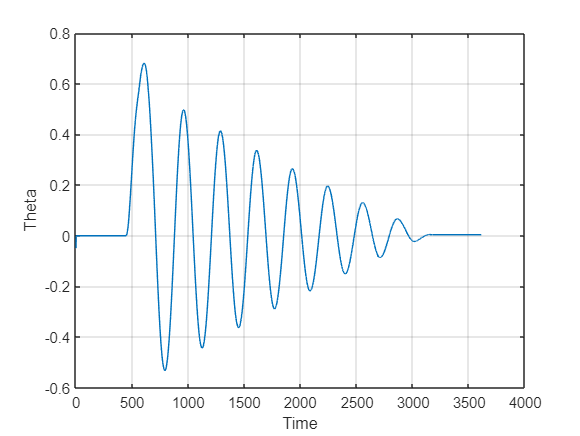

theta = dane_NN.signals(1).values + 1.58;
time = dane_NN.time;

figure
plot(theta)
xlabel('Time')
ylabel('Theta')
grid on

Zostaly podziolone dane zgodnie ze teorią przedstawioną na labolatoriach

y_begin_sample = 602;
y_end_sample = 2875;


training_data_input_1 = theta(y_begin_sample-2:y_end_sample-2)

training_data_input_1 =     0.6777
    0.6770
    0.6782
    0.6797
    0.6798
    0.6796
    0.6807
    0.6804
    0.6800
    0.6808


training_data_input_2 = theta(y_begin_sample-1:y_end_sample-1)

training_data_input_2 =     0.6770
    0.6782
    0.6797
    0.6798
    0.6796
    0.6807
    0.6804
    0.6800
    0.6808
    0.6802


training_data_output = theta(y_begin_sample:y_end_sample)

training_data_output =     0.6782
    0.6797
    0.6798
    0.6796
    0.6807
    0.6804
    0.6800
    0.6808
    0.6802
    0.6809



x_train = [training_data_input_1'; training_data_input_2']

x_train =     0.6777    0.6770    0.6782    0.6797    0.6798    0.6796    0.6807    0.6804    0.6800    0.6808    0.6802    0.6809    0.6801    0.6779    0.6780    0.6768    0.6768    0.6741    0.6738    0.6722    0.6703    0.6682    0.6661    0.6638    0.6626    0.6588    0.6574    0.6535    0.6502    0.6467    0.6449    0.6380    0.6365    0.6324    0.6283    0.6228    0.6196    0.6143    0.6076    0.6035    0.5996    0.5935    0.5893    0.5822    0.5782    0.5723    0.5656    0.5602    0.5538    0.5489
    0.6770    0.6782    0.6797    0.6798    0.6796    0.6807    0.6804    0.6800    0.6808    0.6802    0.6809    0.6801    0.6779    0.6780    0.6768    0.6768    0.6741    0.6738    0.6722    0.6703    0.6682    0.6661    0.6638    0.6626    0.6588    0.6574    0.6535    0.6502    0.6467    0.6449    0.6380    0.6365    0.6324    0.6283    0.6228    0.6196    0.6143    0.6076    0.6035    0.5996    0.5935    0.5893    0.5822    0.5782    0.5723    0.5656    0.5602    0.5538    0.548

time_train = (time(y_begin_sample:y_end_sample) - time(y_begin_sample))'

time_train =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


y_train = training_data_output'

y_train =     0.6782    0.6797    0.6798    0.6796    0.6807    0.6804    0.6800    0.6808    0.6802    0.6809    0.6801    0.6779    0.6780    0.6768    0.6768    0.6741    0.6738    0.6722    0.6703    0.6682    0.6661    0.6638    0.6626    0.6588    0.6574    0.6535    0.6502    0.6467    0.6449    0.6380    0.6365    0.6324    0.6283    0.6228    0.6196    0.6143    0.6076    0.6035    0.5996    0.5935    0.5893    0.5822    0.5782    0.5723    0.5656    0.5602    0.5538    0.5489    0.5426    0.5371


Następnie zostala wytrenowana siec neuronowa:

perf = 3.8540e-06

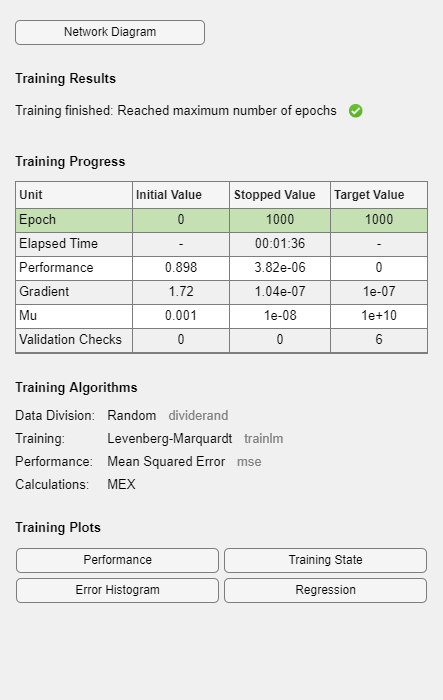

net = feedforwardnet(2, 'trainlm');
net = train(net, x_train, y_train);
view(net);
y_net = net(x_train);
perf = perform(net,y_train, y_net)  

y_net = net(x_train);

sample_time = 0.01;

perf = 3.8462e-06

gensim(net, sample_time)

ans = 'untitled'

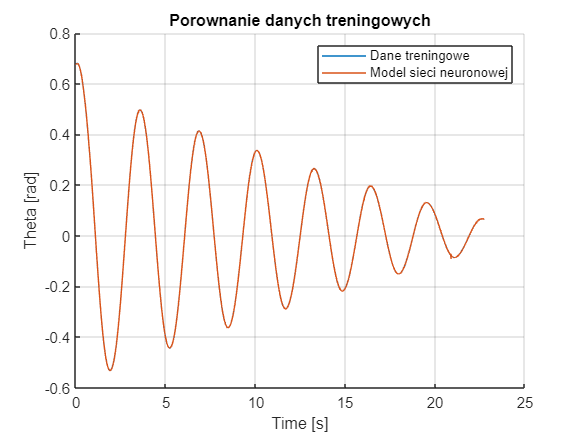

figure();
hold on
plot(time_train, y_train)
plot(time_train, y_net)
hold off
legend("Dane treningowe", 'Model sieci neuronowej')
xlabel('Time [s]')
ylabel('Theta [rad]')
title('Porownanie danych treningowych')
grid on


% err = immse(y_train, y_net)
err = y_net-y_train

err =    -0.0028   -0.0015    0.0003   -0.0007   -0.0023    0.0003   -0.0008   -0.0021    0.0004   -0.0023    0.0005    0.0005   -0.0030    0.0004   -0.0020    0.0018   -0.0030    0.0004   -0.0005   -0.0005   -0.0006   -0.0005   -0.0018    0.0019   -0.0029    0.0019   -0.0011   -0.0002   -0.0021    0.0044   -0.0054    0.0020   -0.0003    0.0011   -0.0025    0.0019    0.0012   -0.0025   -0.0005    0.0021   -0.0020    0.0028   -0.0029    0.0018    0.0008   -0.0010    0.0010   -0.0013    0.0015   -0.0007


err_degree = err * 180/pi

err_degree =    -0.1606   -0.0850    0.0168   -0.0403   -0.1322    0.0181   -0.0469   -0.1214    0.0210   -0.1328    0.0293    0.0298   -0.1736    0.0202   -0.1154    0.1016   -0.1736    0.0231   -0.0273   -0.0297   -0.0353   -0.0292   -0.1003    0.1108   -0.1654    0.1070   -0.0648   -0.0112   -0.1181    0.2546   -0.3091    0.1123   -0.0163    0.0658   -0.1425    0.1067    0.0703   -0.1440   -0.0283    0.1202   -0.1128    0.1608   -0.1660    0.1034    0.0437   -0.0584    0.0557   -0.0738    0.0839   -0.0410


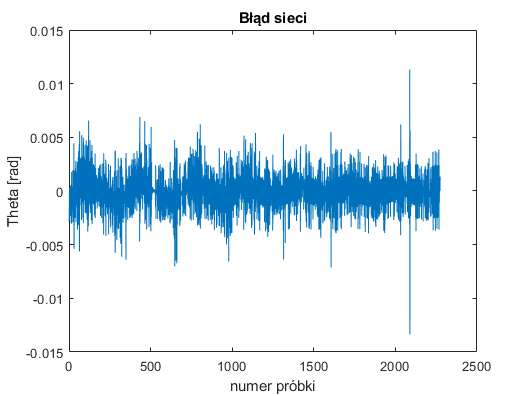

figure;
plot(err)
xlabel('numer próbki')
ylabel('Theta [rad]')
title('Błąd sieci')

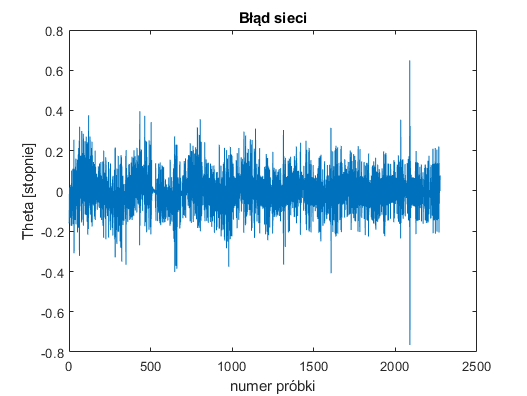


figure;
plot(err_degree)
xlabel('numer próbki')
ylabel('Theta [stopnie]')
title('Błąd sieci')

layers = 1:4;
layers_test = zeros(length(layers), length(training_data_output));

for i=layers
    net = feedforwardnet(i, 'trainlm');
    net = train(net, x_train, y_train);
    
    y_net = net(x_train);
    layers_test(i, :) = y_net;
    perf = perform(net,y_train, y_net)
end

perf = 3.8487e-06

perf = 3.8449e-06

perf = 3.8550e-06

perf = 3.8450e-06

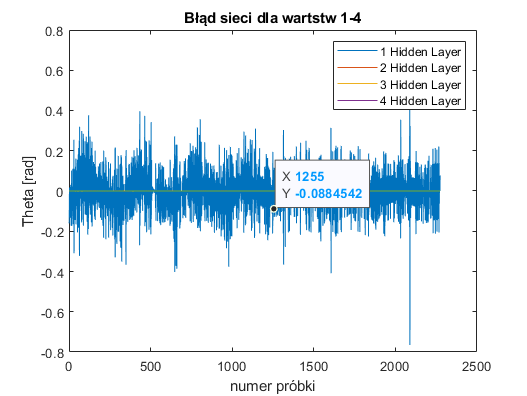

err = layers_test - y_net;
hold on
plot(err(1, :))
plot(err(2, :))
plot(err(3, :))
plot(err(4, :))
hold off
xlabel('numer próbki')
ylabel('Theta [rad]')
title('Błąd sieci dla wartstw 1-4')
legend('1 Hidden Layer', '2 Hidden Layer', '3 Hidden Layer', '4 Hidden Layer')

pendulum_theta = walidacja_modelu_sieci.signals(1).values;
neuron_network1_model_theta = walidacja_modelu_sieci.signals(2).values;
neuron_network2_model_theta = walidacja_modelu_sieci.signals(3).values;
time_validation = walidacja_modelu_sieci.time

time_validation =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


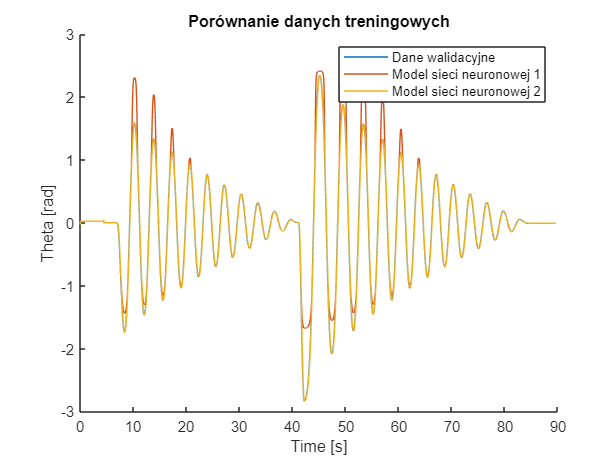

figure();
hold on
plot(time_validation, pendulum_theta)
plot(time_validation, neuron_network1_model_theta)
plot(time_validation, neuron_network2_model_theta)
hold off
legend("Dane walidacyjne", 'Model sieci neuronowej 1', "Model sieci neuronowej 2")
xlabel('Time [s]')
ylabel('Theta [rad]')
title('Porównanie danych treningowych')